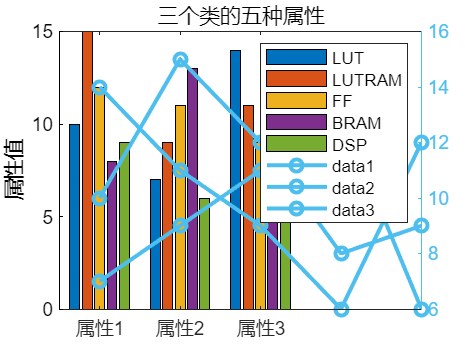

% 定义属性的名称和数据
attributes = {'(1,8,8)', '(2,8,8)', '(3,8,8)', '(4,8,8)',...
    '(1,8,16)','(2,8,16)','(3,8,16)','(4,8,16)',...
    };

class1_data = [10, 15, 12, 8, 9];
class2_data = [7, 9, 11, 13, 6];
class3_data = [14, 11, 9, 6, 12];

% 创建柱状图
figure;
bar([class1_data; class2_data; class3_data]);
set(gca, 'XTickLabel', attributes);
ylabel('属性值');
title('三个类的五种属性');

% 自动调整柱状图的颜色
colormap(gca, 'parula');

% 添加图例
legend('LUT', 'LUTRAM', 'FF', 'BRAM', 'DSP');

% 创建折线图
hold on;
yyaxis right;  % 使用右边坐标轴
plot(class1_data, '-o', 'LineWidth', 2);
plot(class2_data, '-o', 'LineWidth', 2);
plot(class3_data, '-o', 'LineWidth', 2);
hold off;

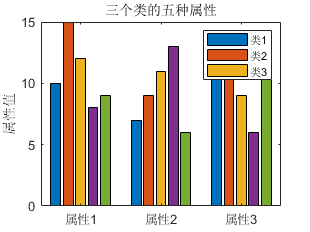

% 定义属性的名称和数据
attributes = {'属性1', '属性2', '属性3', '属性4', '属性5'};
class1_data = [10, 15, 12, 8, 9];
class2_data = [7, 9, 11, 13, 6];
class3_data = [14, 11, 9, 6, 12];

% 创建柱状图
figure;

bar([class1_data; class2_data; class3_data]);
set(gca, 'XTickLabel', attributes);
legend('类1', '类2', '类3');
ylabel('属性值');
title('三个类的五种属性');






% 生成示例数据
x = 1:10;
A = 2*x;
B = x.^2;

% 创建图形窗口
figure;

% 绘制 A 数据（左边坐标轴）
yyaxis left;
plot(x, A, 'b-*');
ylabel('A');

% 创建右边坐标轴
ax = gca;  % 获取当前坐标轴
ax.YAxis(1).Color = 'b';  % 设置左边坐标轴颜色
ax.YAxis(2).Color = 'r';  % 设置右边坐标轴颜色
ax.YAxis(2).Scale = 'log';  % 设置右边坐标轴为对数刻度

% 绘制 B 数据（右边坐标轴）
hold on;
plot(x, B, 'r-o');
ylabel('B (log scale)');

% 设置 x 轴标签
xlabel('x');

% 添加图例
legend('A', 'B');

% 标题
title('Data A and B');

% 网格线
grid on;